# Flux computation

set_demo_defaults

In groundwater hydrology, and many other applications, the flux is given by the gradient of a potential. In this case by Darcy's law


$$\mathbf{q} = -K\nabla h$$


where head,$h$, is the potential. The discrete flux is readily approximated using the existing discrete gradient as

`q = -Kd*G*h`.

This works well in the interior of the domain but fails on the boundary where the discrete gradient is zero by construction, as the example below illustrates.

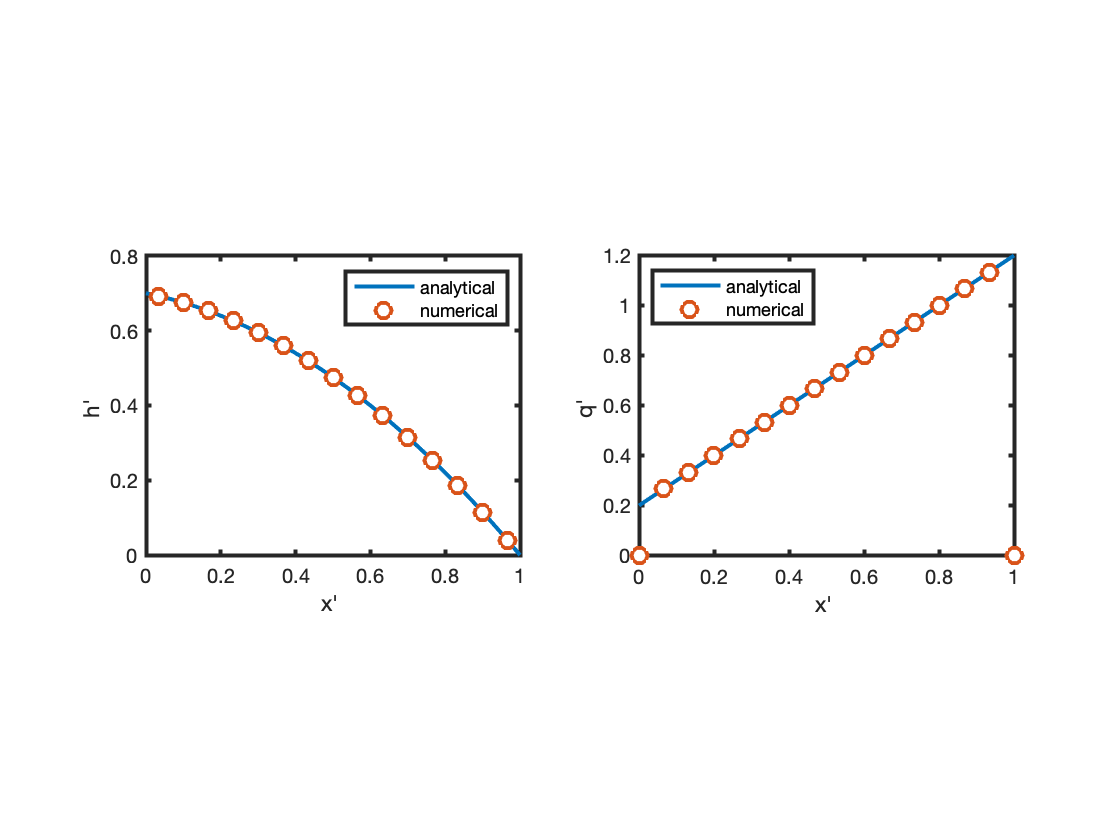

clear
q_ana = @(x,Pi) x + Pi;
h_ana = @(x,Pi) .5*(1-x.^2)+Pi*(1-x);
x_ana = linspace(0,1,1e2);



Pi = 0.2;
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 15;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*G; fs = ones(Grid.Nx,1);

BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = h_ana(Grid.xc(Grid.dof_xmax),Pi);

BC.dof_neu = Grid.dof_xmin;
BC.dof_f_neu = Grid.dof_f_xmin;
BC.qb = Pi;
[B,N,fn] = build_bnd(BC,Grid,I);

h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = -G*h;

figure
subplot 121
plot(x_ana,h_ana(x_ana,Pi)), hold on
plot(Grid.xc,h,'o','markersize',8,'markerfacecolor','w')
xlabel 'x'' ', ylabel 'h'' '
legend('analytical','numerical')
pbaspect([1 .8 1])

subplot 122
plot(x_ana,q_ana(x_ana,Pi)), hold on
plot(Grid.xf,q,'o','markersize',8,'markerfacecolor','w')
xlabel 'x'' ', ylabel 'q'' '
legend('analytical','numerical','location','northwest')
pbaspect([1 .8 1])

## Residual of the discrete equation

The residual of of the linear system `L*h=fs` is given by `r = L*h-fs` and provides a measure of how well the system has been solved. For a direct solver such that is used for the backslash operator in Matlab we expect the linear system to be solved exactly so that `r = 0`. Let's check the residual for the example problem

res = L*h-fs;
figure
plot(Grid.xc,res,'o','markersize',8,'markerfacecolor','w'), hold on


The residual is zero in the center but not on the boundaries! Note that the magnitude and sign of the residual are clearly related to the magnitude and direction of the flux. 

- On the left boundary the residual is smaller and positive - here we have a small inflow due to polar recharge!

- On the right boundary the residual is larger and negative -  here we have outflow into the ocean that is larger than the polar rechage because precipitation has been added along the way

How come we get the correct solution to our problem if the linear system is not solve exactly?

- On the right: We are not actually solving the problem on the Dirichlet boundary, because we are eliminating this constraint.

- On the left: The Neumann boundary condition actually adds an additional r.h.s. and we are solving a augmented residual: `r_n = L*h-fs-fn`.

Let's check if the augmented residual is satisfied on the left:

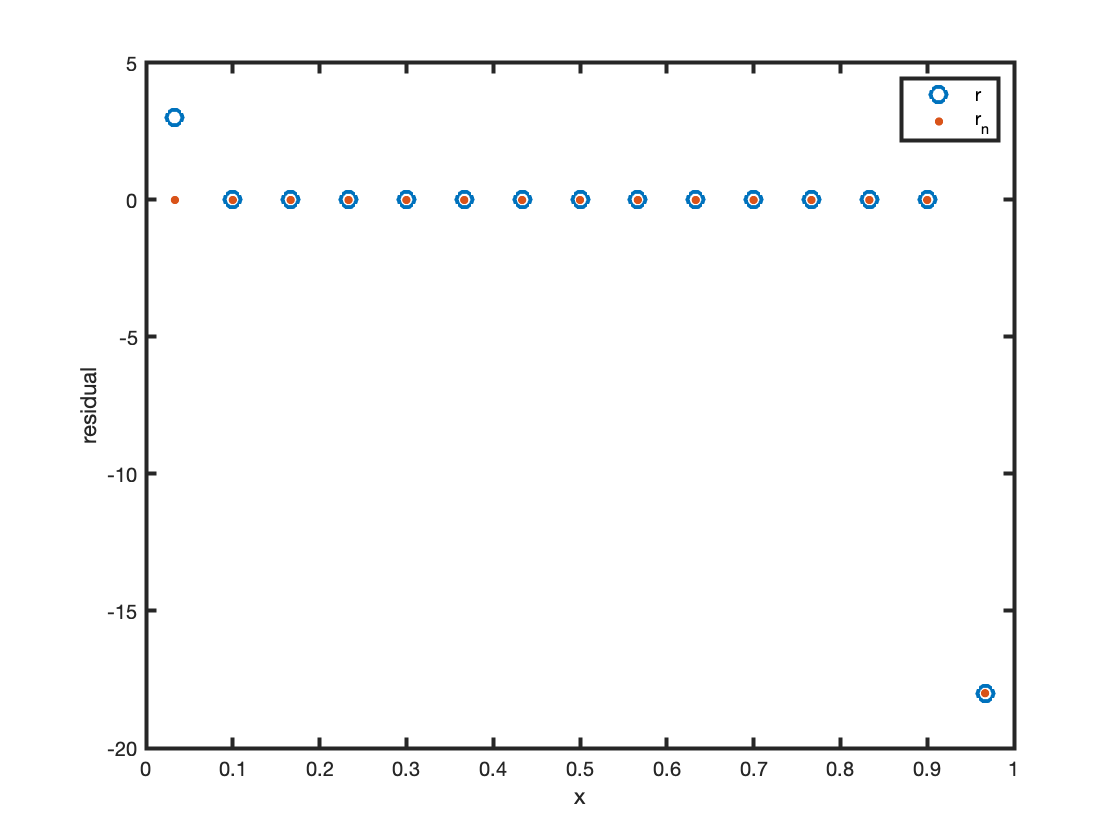

res_n = L*h-fs-fn;
plot(Grid.xc,res_n,'.')
xlabel 'x', ylabel 'residual'
legend('r','r_n')

The augmented residual is zero, because that is the actual equation we are solving on the boundary. Since `r_n = r - fn = 0`, it follows that `r = fn `on the Neumann boundary. 

## Flux reconstruction

#### Neumann boundary

Remember that we computed `fn` from the prescribed boundary flux as

`fn = qb A/V`

Since `fn = r` on the Neumann boundary we can reverse this argment to reconstruct the flux from `r` as `qb = r*V/A`.

qb_neu = res(1)*Grid.V(1)/Grid.A(1)

qb_neu = 0.2000

Which is, of course, exactly $\Pi=0.2$ that we have prescribed. We need to be careful because the above reconstruction mixes quantities from cell centers and cell face. so more generally we have

qb_neu = res(BC.dof_neu)*Grid.V(BC.dof_neu)/Grid.A(BC.dof_f_neu)

qb_neu = 0.2000

figure
plot(x_ana,q_ana(x_ana,Pi)), hold on
plot(Grid.xf,q,'o','markersize',8,'markerfacecolor','w')
plot(Grid.xf(1),qb_neu,'go','markersize',8,'markerfacecolor','w')
xlabel 'x', ylabel 'flux: q'

#### Dirichlet boundary

On the Dirichlet boundary the resdual is also non-zero and size and mangnitude suggest it is also related to the outflow across the boundary. Applying the same flux reconstruction

qb_dir = res(BC.dof_dir)*Grid.V(BC.dof_dir)/Grid.A(BC.dof_f_dir)

qb_dir = -1.2000

Comparing with the plot we can that the magnitude is correct but the sign is of. The flux reconstruction gives us a negative number because we have an outflow from the domain. In the analytic solution the flux is positive because it is in the positive coordinate direction. 

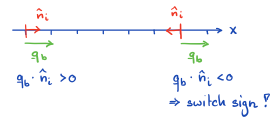

Hence, on the left boundary the sign of the flux will generally match and on the right boundary the sign must be flipped. This sign switch is independen of the type of boundary condition! Hence the correct flow across the right boundary is

qb_dir = -res(BC.dof_dir)*Grid.V(BC.dof_dir)/Grid.A(BC.dof_f_dir)

qb_dir = 1.2000

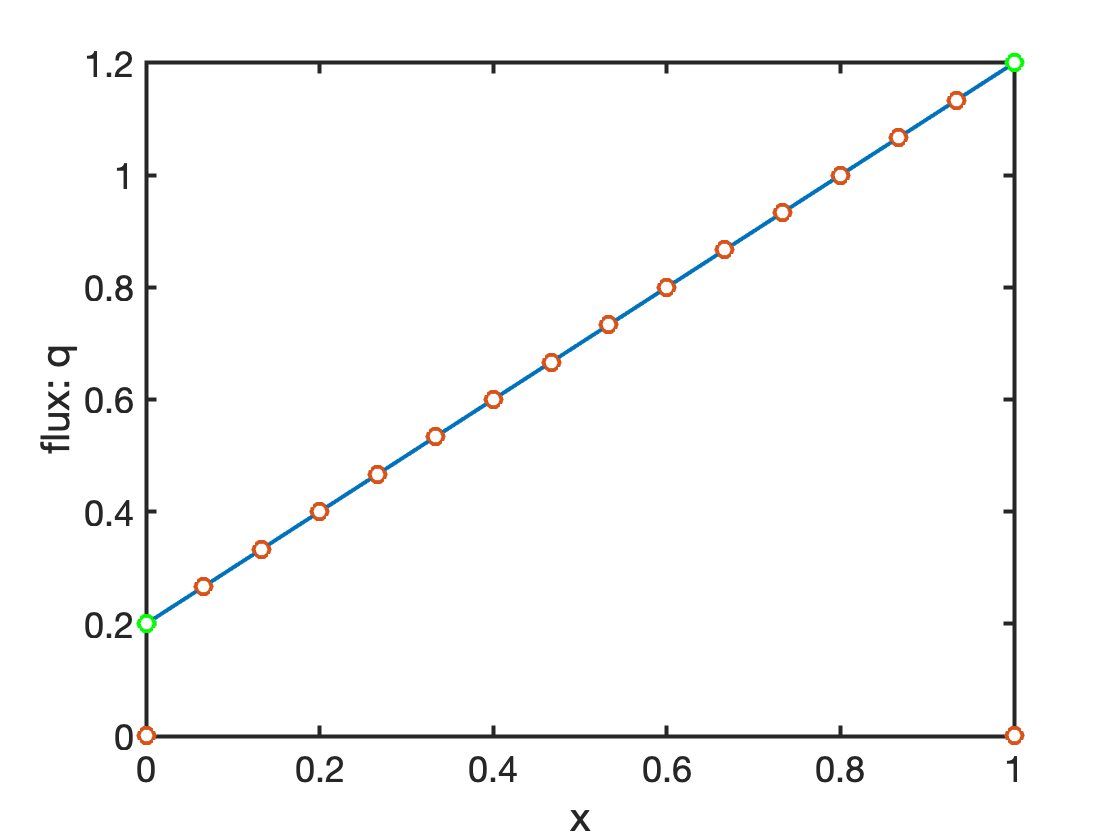

plot(Grid.xf(BC.dof_f_dir),qb_dir,'go','markersize',8,'markerfacecolor','w')

Note, this flux reconstruction gives us a flux that exactly conserves mass, i.e., it is discretely conservative! In 1D this ensures that we get the exact answer. In higher dimensions we won't get exact fluxes, but we will get exact mass balance -  the sum of the in/out flow will exactly balance the fluid added/subtracted by sinks and sources withoin the domain.

### General Implementation of flux reconstruction

Strictly we only need to reconstruct the flux on Dirichlet boundary, because we have specified the boundary flux on the Neumann boundary. However, we still have to paste the Neuman BCs into the flux vector so it becomes simpler to apply a uniform flux reconstruction to all boundaries that are not natural (no flow).  Also it is a good check to make sure that we recover the prescribed boundary conditions. For the flux reconstruction on the boundary we define the following vectors:

- `dof_cells = [BC.dof_dir;BC.dof_neu];`

- `dof_faces = [BC.dof_f_dir;BC.dof_f_dir];`

So that we can apply the reconstruction to both at the at the same time and paste it into the correct locations in the flux vector

`q(dof_faces) = the_sign.*res(dof_cells)*Grid.V(dof_cells)/Grid.A(dof_faces)`

Here `the_sign` is a vector of the same length as `dof_cells` and `dof_faces` that is either 1 or -1 depending if the boundary condition is applied at xmin or xmax. 

All of this will be done within a function called `comp_flux.m`. 